% 加载 carsmall 数据集。
% 考虑一个模型，该模型根据汽车的马力和重量预测汽车的燃油效率。 确定样本大小。
% Load the carsmall data set.
% Consider a model that predicts a car's fuel efficiency given its horsepower and weight. Determine the sample size.

load carsmall
tbl = table(Horsepower,Weight,MPG);
N = size(tbl,1);
% 将数据划分为训练集和测试集。 保留 10% 的数据进行测试。
% Partition the data into training and test sets. Hold out 10% of the data for testing.

rng(10); % For reproducibility
cvp = cvpartition(N,'Holdout',0.1);
idxTrn = training(cvp); % Training set indices
idxTest = test(cvp);    % Test set indices

## 训练线性 SVM 回归模型。 标准化数据。

Train a linear SVM regression model. Standardize the data.

Mdl = fitrsvm(tbl(idxTrn,:),'MPG','Standardize',true);
% Mdl is a RegressionSVM model.
% Mdl 是一个 RegressionSVM 模型。

## 工作（预测）阶段

预测训练集的响应。

YFit1 = predict(Mdl,tbl(idxTrn,:));
% 预测测试集的响应。
% Predict responses for the test set.
YFit2 = predict(Mdl,tbl(idxTest,:));

## 查看结果

创建一个包含观察到的响应值和预测的响应值并排的表 Create a table containing the observed response values and the predicted response values side by side.

table(tbl.MPG(idxTest),YFit2,'VariableNames',...
    {'ObservedValue','PredictedValue'})

ans = 10×2 table
    ObservedValue    PredictedValue
    _____________    ______________

          14             9.4833    
          27             28.938    
          10              7.765    
          28             27.155    
          22             21.054    
          29             31.484    
        24.5             30.306    
        18.5              19.12    
          32             28.225    
          28             26.632    


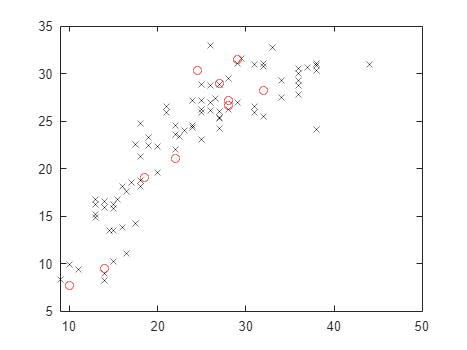


% 画图
plot(tbl.MPG(idxTrn),YFit1,'kx');hold on
plot(tbl.MPG(idxTest),YFit2,'ro')